# Práctica 1. La función de densidad de probabilidad de la magnitud

## Parte 2. Distribución uniforme

clear     % Limpiamos el workspace
clc       % Limpiamos la ventana de comandos
close all % Cerramos todas las figuras

### a) Generación del proceso estocástico (una realización)

% Número de muestras por realización
n = 10000

n = 10000

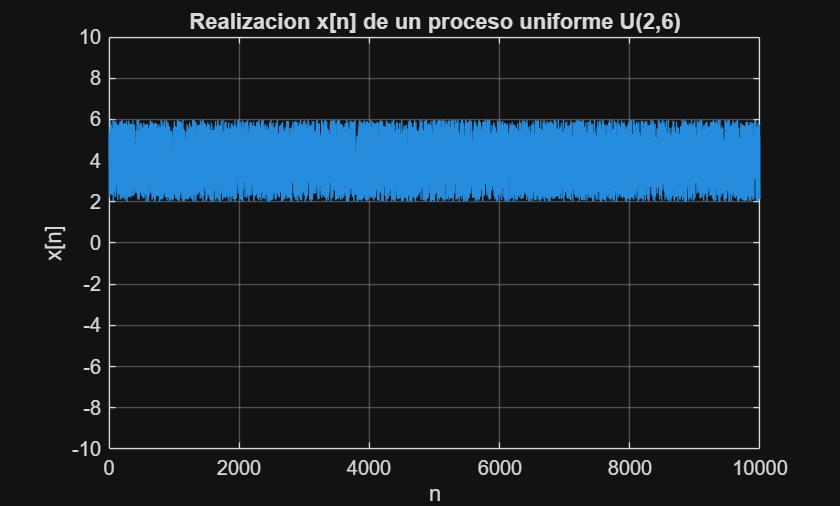


% Valor mínimo
a = 2;

% Valor máximo
b = 6;

% Generación de una realización x[n]
x_n = a + (b-a)*rand(1,n);

% Representación gráfica de una realización
figure(1)
plot(x_n);grid on
xlabel('n');ylabel('x[n]')
ylim([-10 10])
title(['Realizacion x[n] de un proceso uniforme U(',num2str(a),',',num2str(b),')'])

### b) Generación del histograma

% Intervalos de histograma
intervalos = 30

intervalos = 30

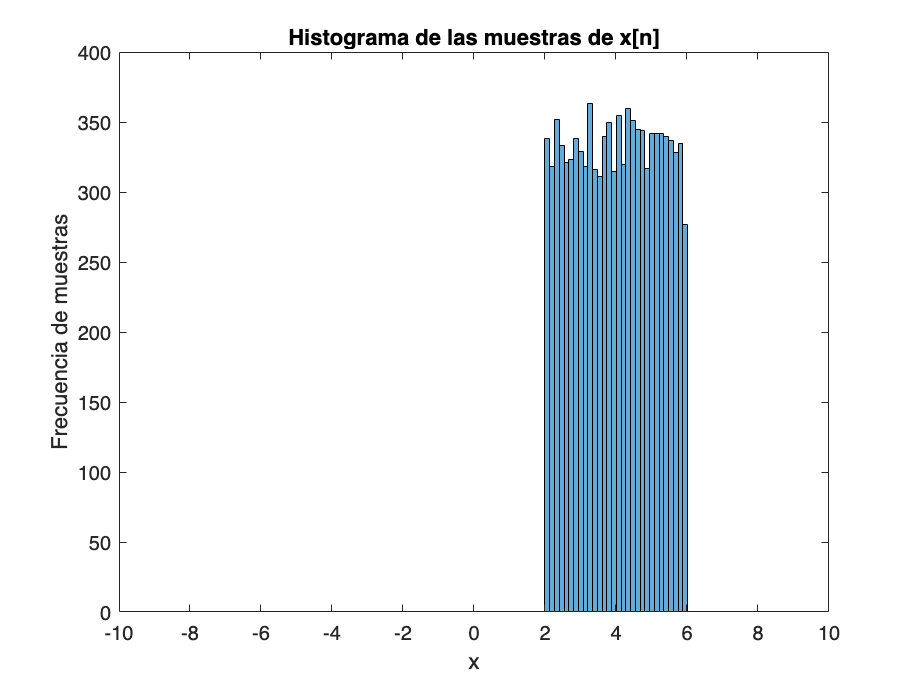


% Cálculo y representación del histograma de x[n]
h = histogram(x_n,intervalos);
xlabel('x')
ylabel('Frecuencia de muestras')
xlim([-10 10])
title('Histograma de las muestras de x[n]')

### c) Estimación de la FDA

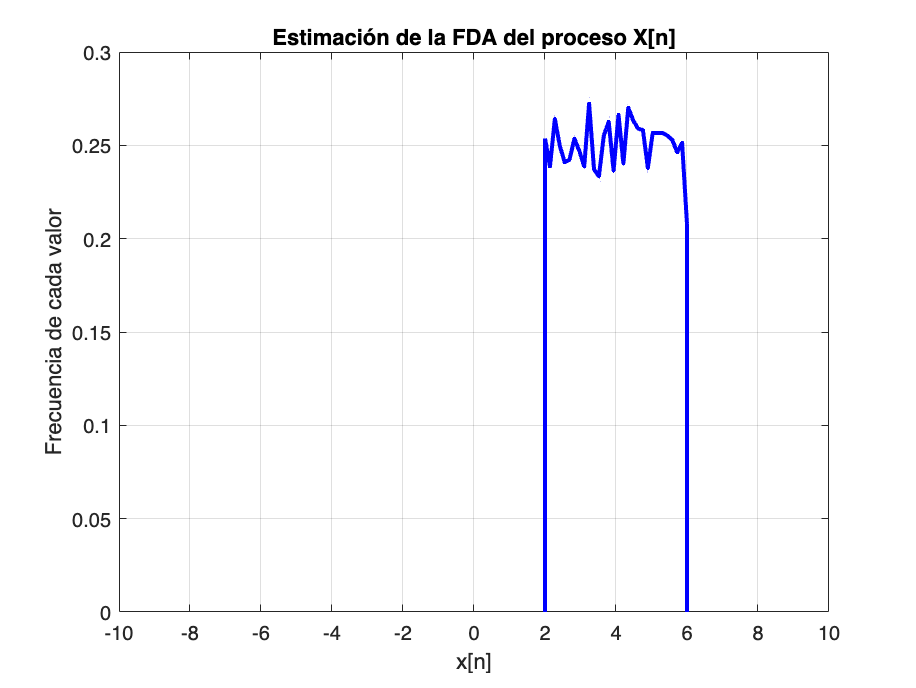

% Cálculo del rango, anchura y área de la FDA de x[n]
rango = max(x_n) - min(x_n);
anchura = rango/intervalos;
area = sum(h.Values)*anchura;

% Frecuencia de cada valor
f = h.Values/area;

% Cálculo de la FDA
x = linspace(min(x_n),max(x_n),length(f));

% Representación gráfica de la FDA
figure(2)
plot(x,f,'b','LineWidth',2);grid on
hold on;
plot([a a],[0 f(1)],'b','LineWidth',2);
plot([b b],[0 f(end)],'b','LineWidth',2);
hold off;
xlabel('x[n]')
ylabel('Frecuencia de cada valor')
axis([-10 10 0 0.3])
title('Estimación de la FDA del proceso X[n]')

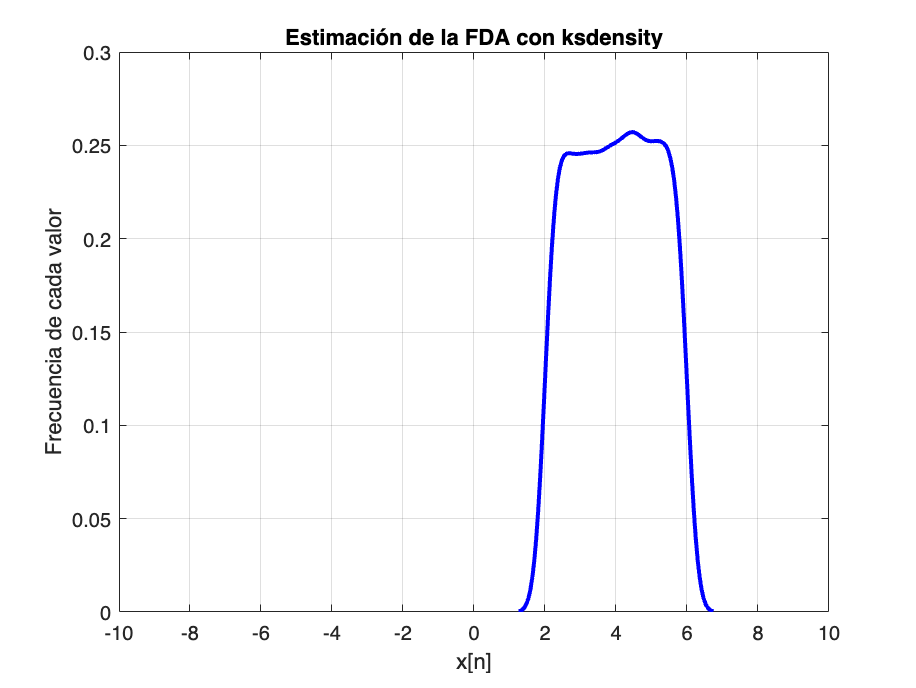

% Estimación con la función ksdensity
figure(3)
[FDE,x_FDE] = ksdensity(x_n);
plot(x_FDE,FDE,'b','LineWidth',2); grid on
xlabel('x[n]')
ylabel('Frecuencia de cada valor')
axis([-10 10 0 0.3])
title('Estimación de la FDA con ksdensity')

### d) Generación de la FDP uniforme de primer orden

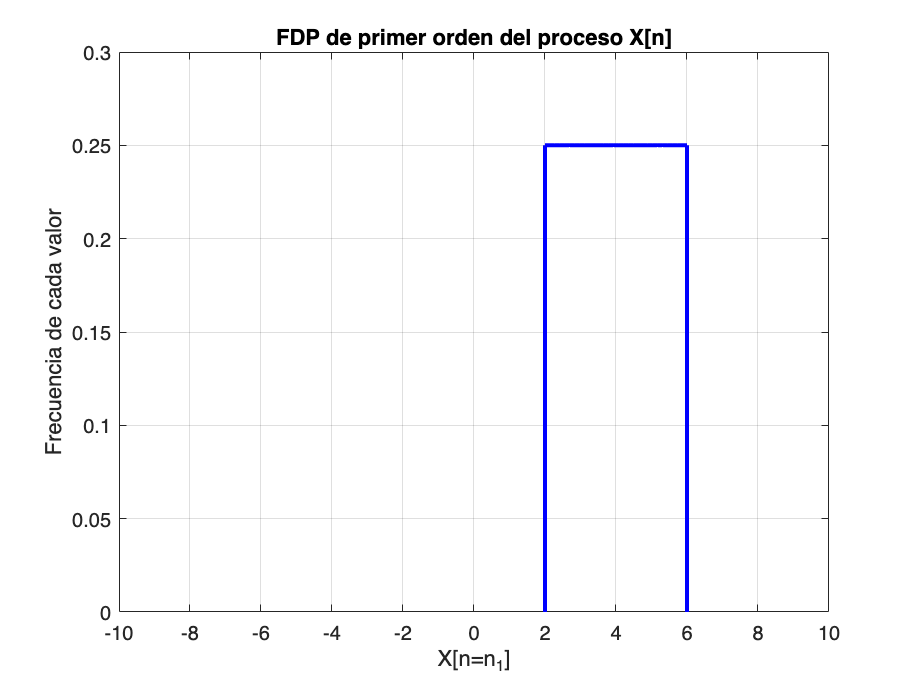

% Expresión teórica de la FDP*
uniforme = ones(1,length(x))*(1/(b-a));
% Representación gráfica de la FDP
figure(4)
plot(x,uniforme,'b','LineWidth',2);grid on
hold on;
plot([a a],[0 1/(b-a)],'b','LineWidth',2);
plot([b b],[0 1/(b-a)],'b','LineWidth',2);
xlabel('X[n=n_1]')
ylabel('Frecuencia de cada valor')
axis([-10 10 0 0.3])
title('FDP de primer orden del proceso X[n]')

*recuerde que la FDP de una distribución uniforme se expresa tal que


$$f_X(x)= \frac{1}{b-a},\forall x\in a\leq x\leq b$$


### e) Comparación de la FDP y la FDA

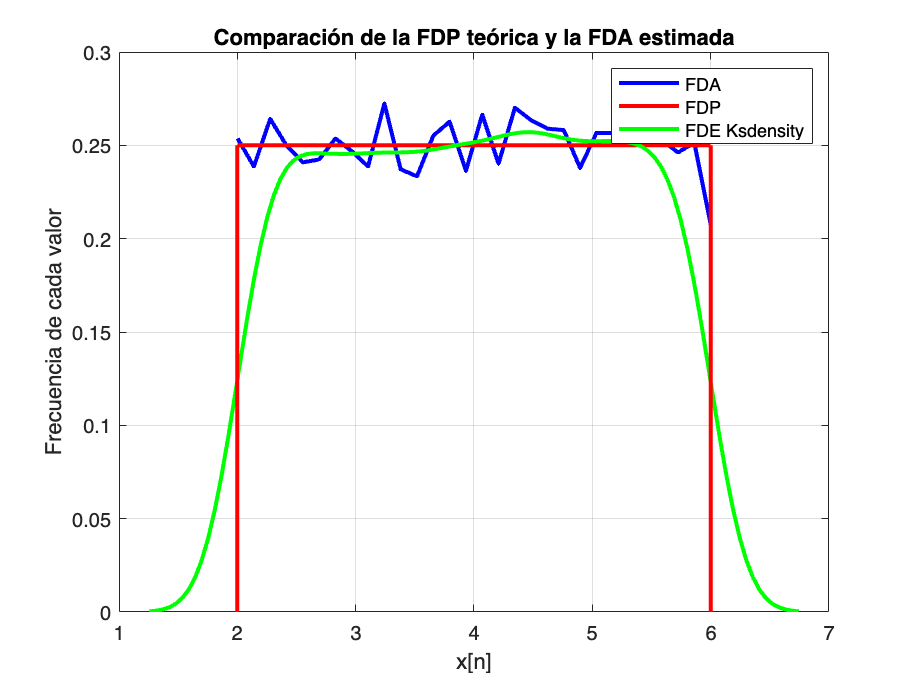

% Representación gráfica de FDA y FDP
figure(5);
plot(x,f,'b','LineWidth',2);grid on
xlabel('x[n]')
ylabel('Frecuencia de cada valor')
hold on;
plot(x,uniforme,'r','LineWidth',2);
plot(x_FDE,FDE,'g','LineWidth',2);
plot([a a],[0 1/(b-a)],'r','LineWidth',2);
plot([b b],[0 1/(b-a)],'r','LineWidth',2);
legend('FDA','FDP','FDE Ksdensity');
title('Comparación de la FDP teórica y la FDA estimada')
hold off;

## f) Cálculo de la potecia

% Potencia práctica
Px_practica = sum(x_n.^2)/length(x_n)

Px_practica = 17.3802

% Potencia estimada
Px_estimada = (a+b)^2/4 + (b-a)^2/12

Px_estimada = 17.3333

### g) FDP de segundo orden

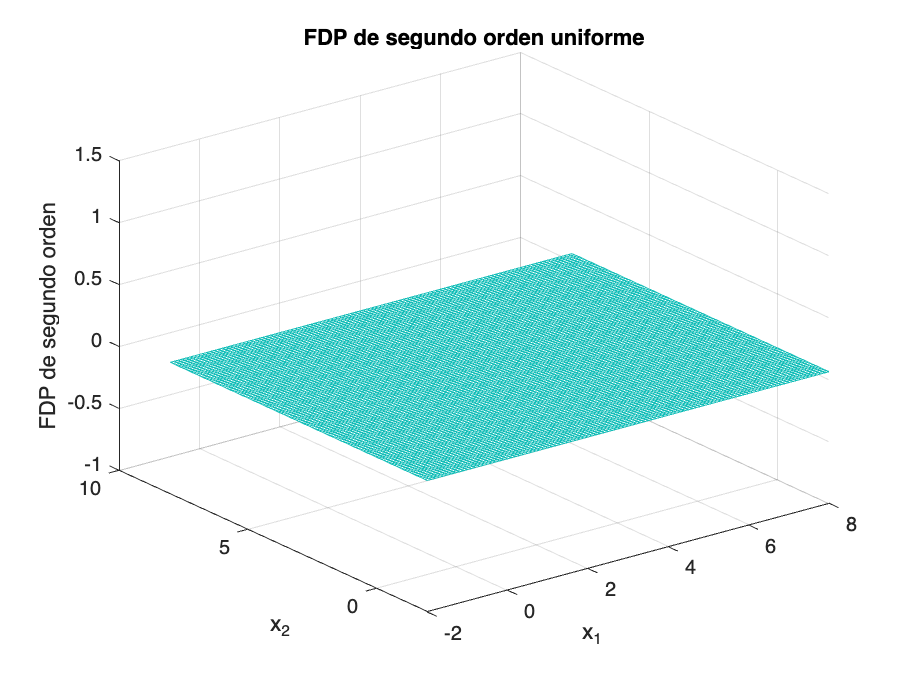

% Distribución de valores
x1 = -2:0.1:8;

% Distribución 1
uniforme1 = ones(1,length(x1))*(1/(b-a));

% Distribución 2
uniforme2 = ones(1,length(x1))*(1/(b-a));

% Matriz de ambas FDP
G = uniforme2'*uniforme1;

% Representación gráfica 3D con mesh
figure(6),
mesh(x1,x1,G)
xlabel('x_1')
ylabel('x_2')
zlabel('FDP de segundo orden')
title('FDP de segundo orden uniforme')

### EXTRA: Media de un proceso estocástico senoidal uniforme

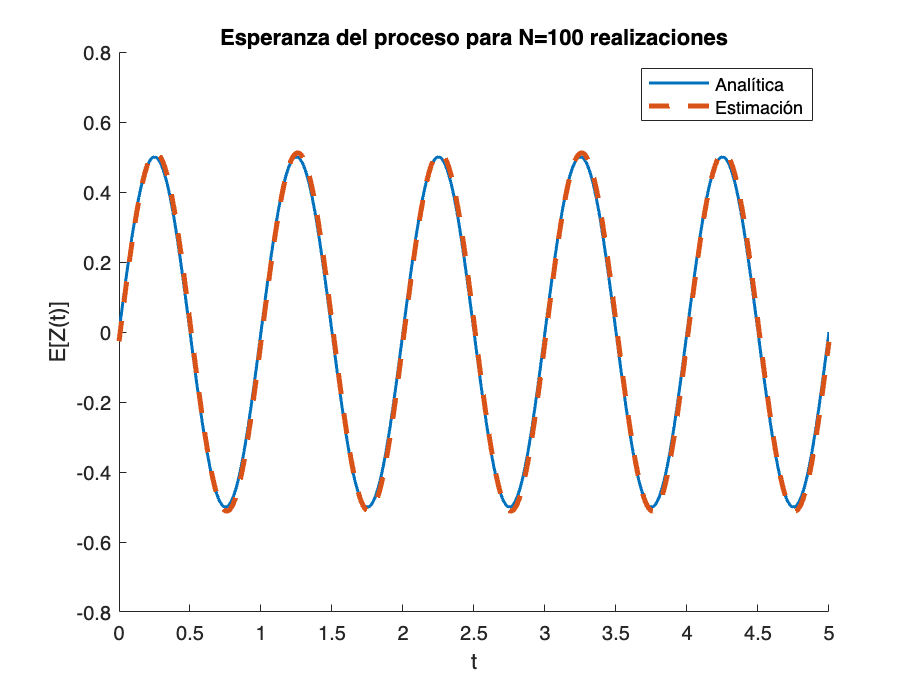

close all

% Parámetros básico senoidales
w0 = 2*pi;
t = 0:0.01:5;

% Número de realizaciones
N_realizaciones = 100;

% Longitud de cada realización
longitud_t = length(t);

% Inicialización de la matriz que contendrá todas las realizaciones
Z = zeros(N_realizaciones,longitud_t);

% Generamos un proceso estocástico por cada realización
for n = 1:N_realizaciones

    % Variable aleatoria uniformemente distribuída en el intervalo (-1,1)
    X = 2*rand - 1;

    % Variable aleatoria uniformemente distribuída en el intervalo (0,1)
    Y = rand;

    % Realización n del proceso Z(t)
    Z(n,:) = X*cos(w0*t) + Y*sin(w0*t);

end

% Cálculo de la media estimada
media_Z_simulacion = mean(Z);

% Cálculo de la media teórica*
media_Z_teorica = 0.5*sin(w0*t);

% Representación gráfica de las medias estimada y teórica
figure(7);hold on
plot(t,media_Z_teorica,'LineWidth',1.5)
plot(t,media_Z_simulacion,'--','LineWidth',2.5)
hold off
xlabel('t');ylabel('E[Z(t)]')
axis([0 5 -0.8 0.8])
legend('Analítica','Estimación')
title(['Esperanza del proceso para N=',num2str(N_realizaciones),' realizaciones'])

*recuerde que la esperanza de un proceso estocástico senoinal uniforme se expresa tal que


$$E[Z(t)]=\frac{1}{2}sin(\omega_0t)$$
